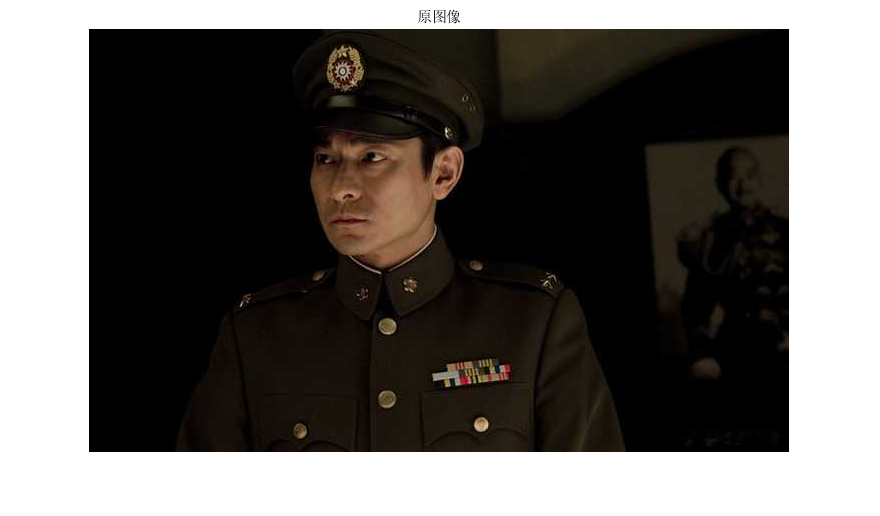

clc;
clear;
I=imread("04-刘德华.jpg");
figure(1)
imshow(I);
title("原图像");

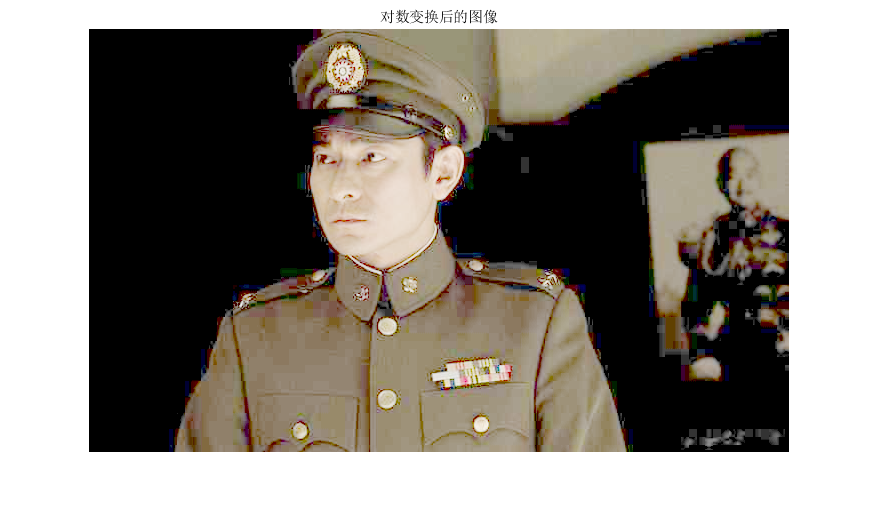

%对数变换，常数c=1
im_log=im2uint8(mat2gray(log(1+double(I))));
figure
imshow(im_log);
title("对数变换后的图像");

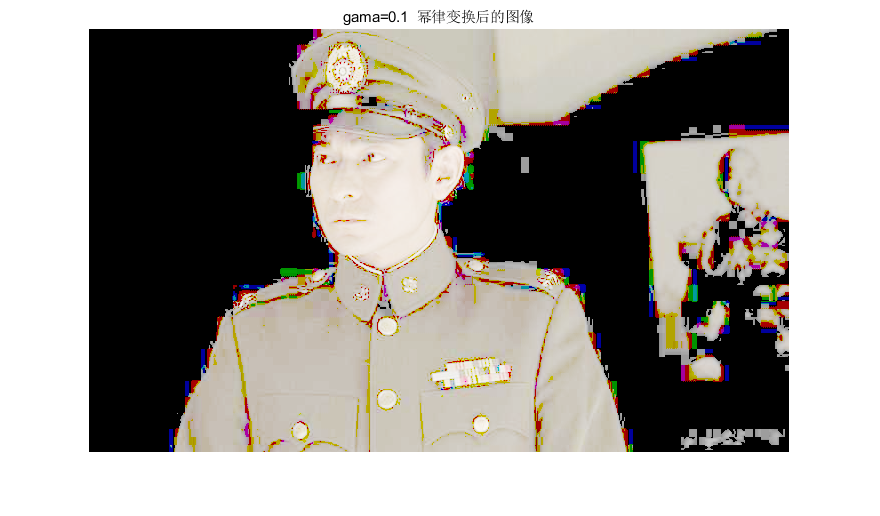

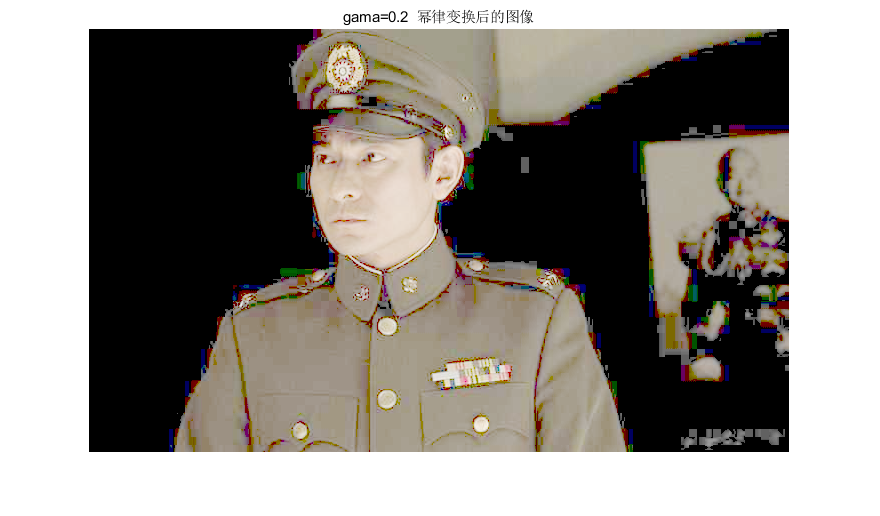

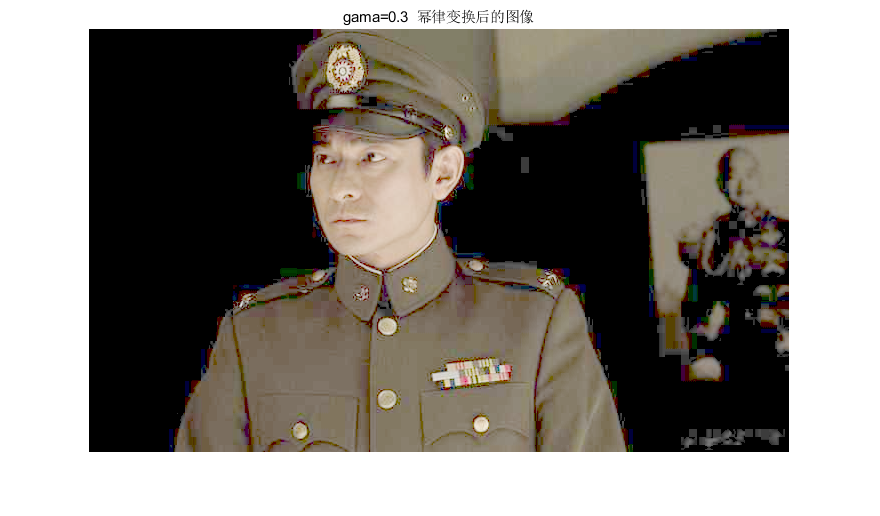

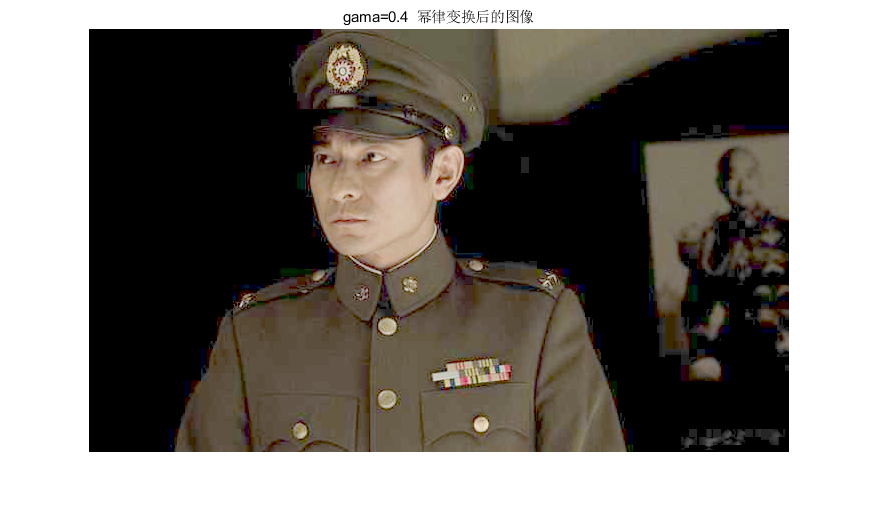

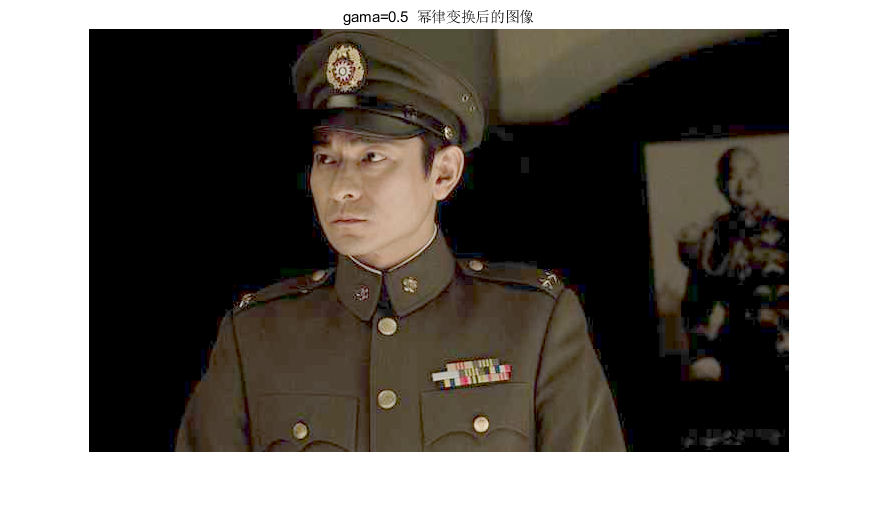

%幂律变换,背景区域灰度级小，为了增强背景，幂次应该小于1
%c=1;
%分别取gama=0.1,0.2,0.3,0.4,0.5
for i=1:5
gama=0.1*i;
%进行幂律变换
im_gama=im2uint8(mat2gray(double(I).^gama));
figure
imshow(im_gama);
title(['gama=',num2str(gama),'  幂律变换后的图像']);
end

%gama=0.3时，效果较好
im_gama=im2uint8(mat2gray(double(I).^0.3));
%储存
imwrite(im_log,'对数变换后的图片.jpg','jpg');
imwrite(im_gama,'幂律变换后的图片.jpg','jpg');